Extracted
Extracted
Extracted
Extracted


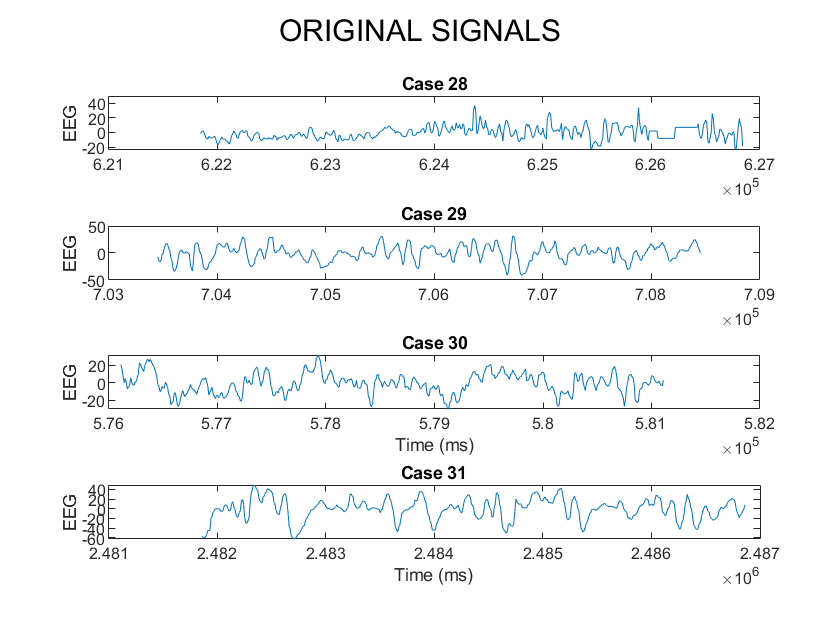

A part of the signals


We've removed data that vary more than 4 std. dev.


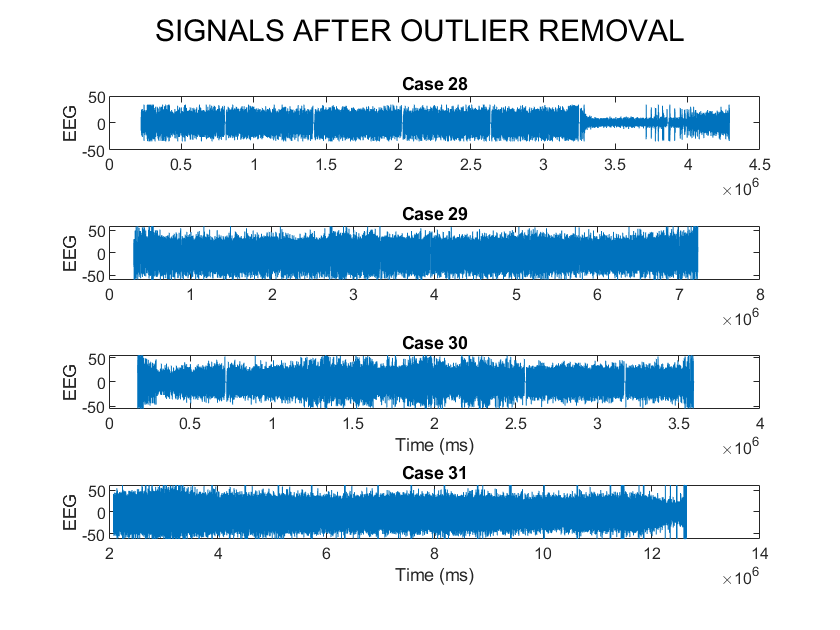

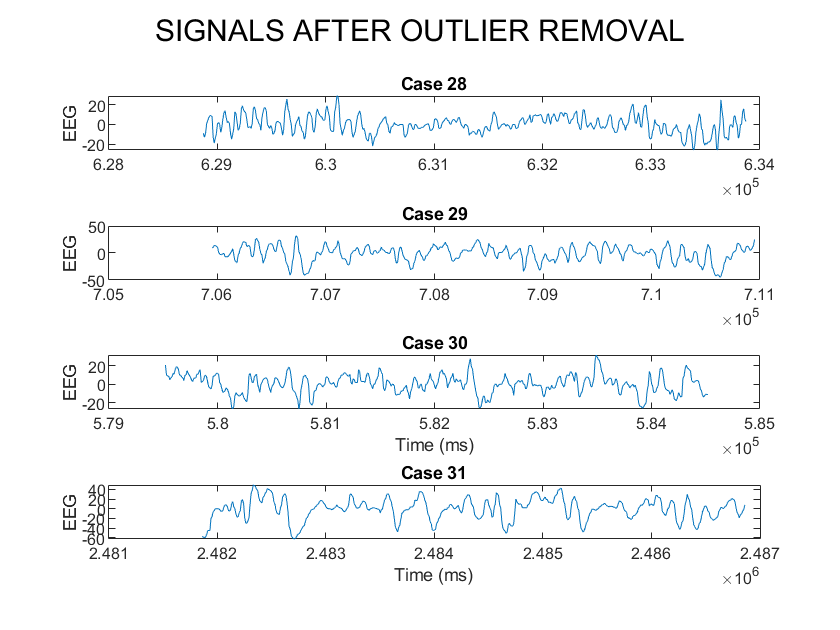

We've filtered line noise


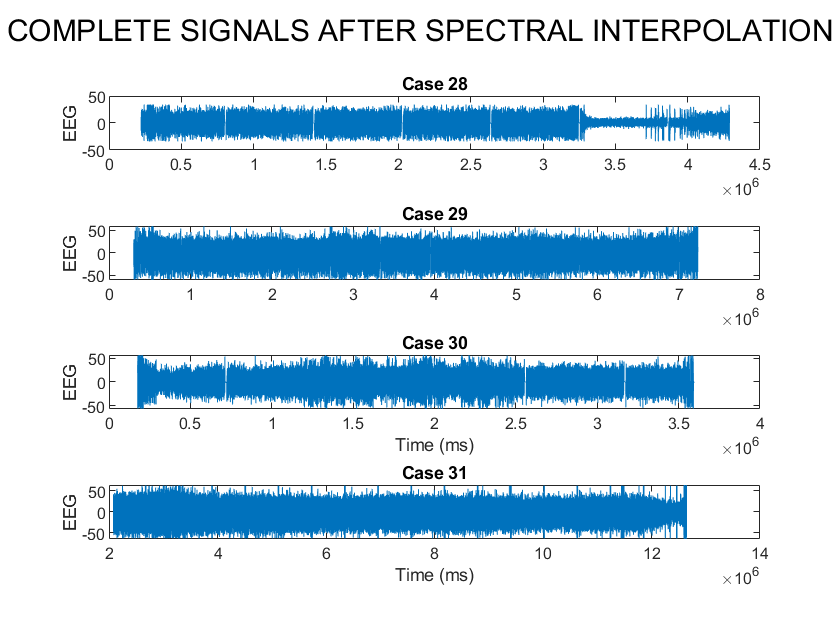

We've filtered line noise


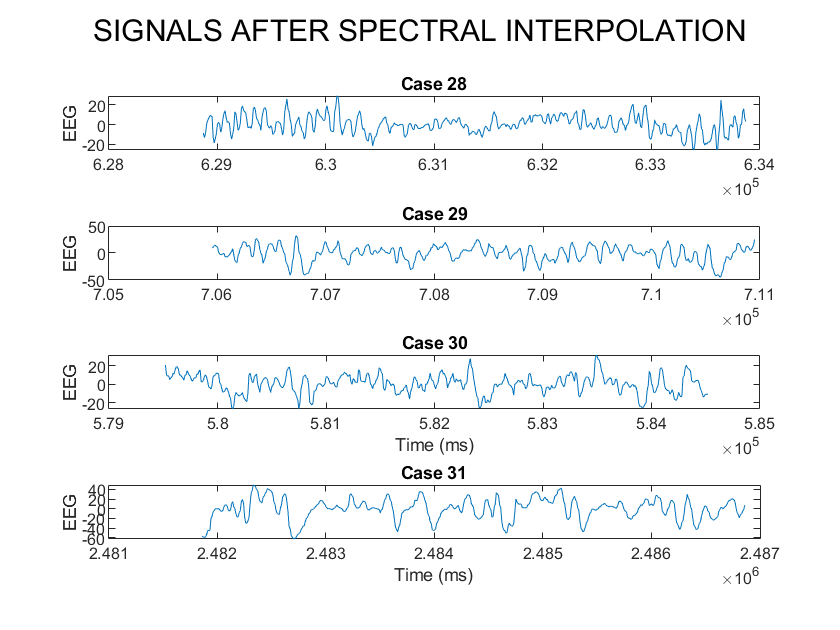

Other Body Vitals Extracted:


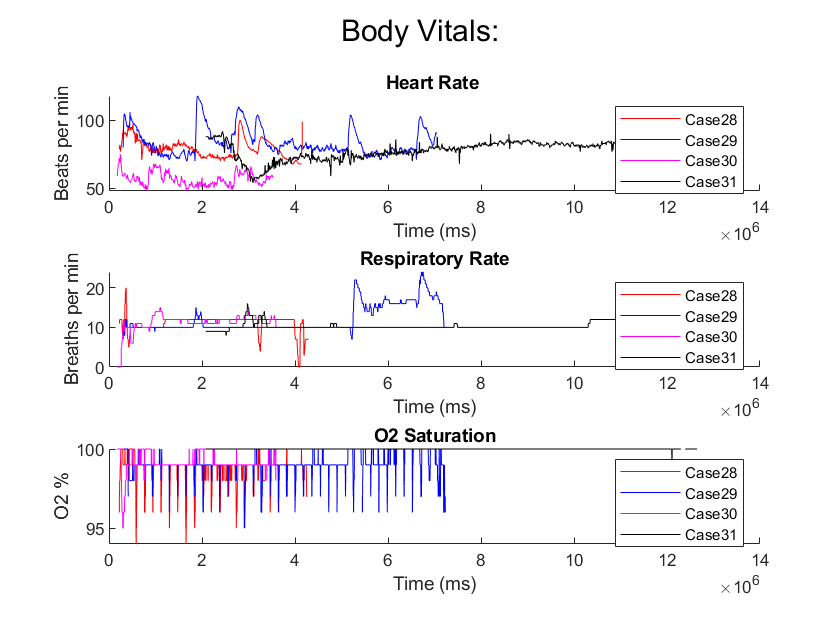

preprocessed = struct with fields:
    new_case28: [1×1 struct]
    new_case29: [1×1 struct]
    new_case30: [1×1 struct]
    new_case31: [1×1 struct]



preprocessed=extract_and_preprocess1("D:\OneDrive - Indian Institute of Science\4th Sem\NSP\NSP-Grant-Proposal\DATA\uqvitalsignsdata","D:\OneDrive - Indian Institute of Science\4th Sem\NSP\NSP-Grant-Proposal\DATA\Pre_Processed_data")

%[hhe_score_se,hhe_score_re,approx_score_se,approx_score_re,bis]=HH_entropy(preprocessed.new_case28)

preprocessed.new_case28.entropies=HH_entropy(preprocessed.new_case28);

'HH_entropy' is not found in the current folder or on the MATLAB path, but exists in:
    D:\OneDrive - Indian Institute of Science\4th Sem\NSP\NSP-Grant-Proposal\MATLAB-COde

Change the MATLAB current folder or add its folder to the MATLAB path.

preprocessed.new_case29.entropies=HH_entropy(preprocessed.new_case29);
preprocessed.new_case30.entropies=HH_entropy(preprocessed.new_case30);
preprocessed.new_case31.entropies=HH_entropy(preprocessed.new_case31);
save("tempHHE.mat","preprocessed",'-mat');
postHHE=preprocessed;
postHHE.new_case28.spectral=getPowerSpecData(preprocessed.new_case28);
postHHE.new_case29.spectral=getPowerSpecData(preprocessed.new_case29);
postHHE.new_case30.spectral=getPowerSpecData(preprocessed.new_case30);
postHHE.new_case31.spectral=getPowerSpecData(preprocessed.new_case31);
save("tempspectral.mat","postHHE",'-mat')
postspectral=postHHE;
postspectral.new_case28.vitals=Vitals(preprocessed.new_case28);
postspectral.new_case29.vitals=Vitals(preprocessed.new_case29);
postspectral.new_case30.vitals=Vitals(preprocessed.new_case30);
postspectral.new_case31.vitals=Vitals(preprocessed.new_case31);
save("tempvital.mat","postspectral",'-mat')

fn = fieldnames(postspectral);
datamatrix=[]
for k=1:numel(fn)
    temp=postspectral.(fn{k});
    temp1=cat(2,temp.vitals,temp.spectral,temp.entropies);
    datamatrix=cat(1,datamatrix,temp1);
end
save("forPython.mat","datamatrix",'-v7')